# Compute Gradient Using Automatic Differentiation

Rosenbrock's function is a standard test function for optimization. The `rosenbrock.m` helper function computes the function value and uses automatic differentiation to compute its gradient.

type rosenbrock.m


function [y,dydx] = rosenbrock(x)

y = 100*(x(2) - x(1).^2).^2 + (1 - x(1)).^2;
dydx = dlgradient(y,x);

end


To evaluate Rosenbrock's function and its gradient at the point `[–1,2]`, create a `dlarray` of the point and then call `dlfeval` on the function handle `@rosenbrock`.

x0 = dlarray([-1,2]);
[fval,gradval] = dlfeval(@rosenbrock,x0)

fval =   1x1 dlarray

   104


gradval =   1x2 dlarray

   396   200


Alternatively, define Rosenbrock's function as a function of two inputs, `x1` and x`2`.

type rosenbrock2.m


function [y,dydx1,dydx2] = rosenbrock2(x1,x2)

y = 100*(x2 - x1.^2).^2 + (1 - x1).^2;
[dydx1,dydx2] = dlgradient(y,x1,x2);

end


Call `dlfeval` to evaluate `rosenbrock2` on two `dlarray` arguments representing the inputs `–1` and `2`.

x1 = dlarray(-1);
x2 = dlarray(2);
[fval,dydx1,dydx2] = dlfeval(@rosenbrock2,x1,x2)

fval =   1x1 dlarray

   104


dydx1 =   1x1 dlarray

   396


dydx2 =   1x1 dlarray

   200


Plot the gradient of Rosenbrock's function for several points in the unit square. First, initialize the arrays representing the evaluation points and the output of the function.

[X1 X2] = meshgrid(linspace(0,1,10));
X1 = dlarray(X1(:));
X2 = dlarray(X2(:));
Y = dlarray(zeros(size(X1)));
DYDX1 = Y;
DYDX2 = Y;

Evaluate the function in a loop. Plot the result using `quiver`.

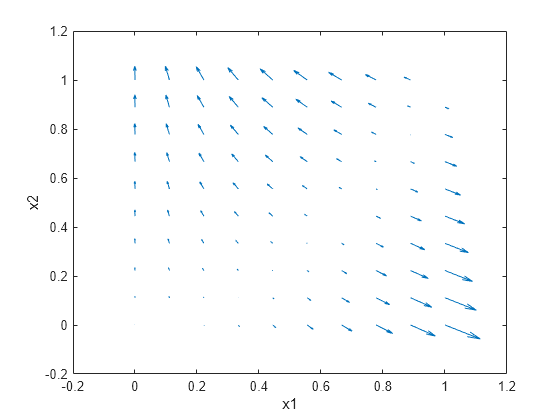

for i = 1:length(X1)
    [Y(i),DYDX1(i),DYDX2(i)] = dlfeval(@rosenbrock2,X1(i),X2(i));
end
quiver(extractdata(X1),extractdata(X2),extractdata(DYDX1),extractdata(DYDX2))
xlabel('x1')
ylabel('x2')

*Copyright 2019 The MathWorks, Inc.*